# Template of Manipulator Short project: Skull tumor surgery

**List of to do:**

The Robotic environment must contain:

1.- Operating table. It can be raised, lowered, and tilted in any direction, and an  auxiliary table for the tools. Use 'patch' or 'fill3' functions to model it.

*Add your comemnts here..... be concise*

clear all

A= 1.1;
L = 2;

aux_A= 0.4;
aux_L = 0.6;

centro_cama = [0 0 1];
centro_aux = [1.5 1.5 1];

FA = eye(4);
FB = eye(4);
yaw = 0; %eje z
roll = 0; % eje x
pitch = 0; % eje y

yaw_aux = 0; %eje z
roll_aux = 0; % eje x
pitch_aux = 0; % eje y

mat_aux = [ 0 0 0 1; aux_A 0 0 1; aux_A aux_L 0 1; 0 aux_L 0 1]';
mat_cama = [ 0 0 0 1; A 0 0 1; A L 0 1; 0 L 0 1]';

r = rpy2r(roll, pitch, yaw,'deg');
r = r2t(r);

r_aux = rpy2r(roll_aux, pitch_aux, yaw_aux,'deg');
r_aux = r2t(r_aux);

FA = transl(centro_cama)*r; %cama 
FB = transl(centro_aux)*r_aux; %mesa aux

mat_cama = transl(centro_cama)*r*mat_cama;
mat_cama = mat_cama(1:3,:);

mat_aux = transl(centro_aux)*r_aux*mat_aux;
mat_aux = mat_aux(1:3,:);

hold on
s= fill3(mat_cama(1,:), mat_cama(2,:), mat_cama(3,:), [1 1 1 1]);
set(s,'facealpha',1);

s2= fill3(mat_aux(1,:), mat_aux(2,:), mat_aux(3,:), [0.7 0.7 0.7]);
set(s2,'facealpha',1);

trplot(eye(4)); % mundo
trplot(FA, ... % Plot frame FA with all the . See 'help trplot'
    'frame', 'A', ...
    'color', 'b',...
    'text_opts', {'FontSize', 12, 'FontWeight', 'bold'},...
     'length',1,...
    'arrow',...
    'axis',[-1 1 -1 1 -1 1],...
    'view',[150,30],...
    'width', 1.2);
trplot(FB, ... % Plot frame FB with all the . See 'help trplot'
    'frame', 'A', ...
    'color', 'b',...
    'text_opts', {'FontSize', 12, 'FontWeight', 'bold'},...
     'length',1,...
    'arrow',...
    'axis',[-1 1 -1 1 -1 1],...
    'view',[150,30],...
    'width', 1.2);

axis([-3 6 0 5 0 5])


2.- A 3D model of a human body on the operating table. Use the Workspace given, or other you might find.

*Add your comemnts here..... be concise*

altura_human = 1.80;

load('SP_material/F_V_Human_Body.mat');
% Para redimencionar al cuerpo multiplicamos los vertices
max_y = max(V(:,2));

tamano = altura_human/max_y;

V = V*tamano;
% Buscamos la anchura después de hacer el escalado.
min_z = min(V(:,3));

%centramos al humano en la mesa
centrado = altura_human/2;

V(:,4) = ones(size(V,1),1); % Añadir fila de 1 para poder trasladar
V = V'; % Transponer para hacer la multiplicacion
V = transl(A/2,-centrado+L/2,-min_z)*V;
V = transl(centro_cama(1),centro_cama(2),centro_cama(3))*r*V;
V = V(1:3,:);
V = V';


stlPlot(V,F,'human')
alpha 0.4;
axis equal;

3.- A human skull model, embedded in the head of the human. Place the fiducials.

*Add your comemnts here.....be concise*

%fv = stlread('SP_material/Crani.stl');
load('Crani.mat');
tamano_crani = 0.075;

% Para redimencionar al cuerpo multiplicamos los vertices
max_y = max(fv.vertices(:,2));

tamano = tamano_crani/max_y;
%V2 = fv.vertices;
%fv.vertices = V2;
fv.vertices = fv.vertices*tamano;
% Buscamos la anchura después de hacer el escalado.
max_y = max(fv.vertices(:,2));
max_z = max(fv.vertices(:,3)); % para luego centrar la parte de arriba del craneo con la parte de arriba de la cabeza del humano

% añadimos el fiducial
fiducial_y = tamano_crani;  % calculamos la posición
fiducial_x = tamano_crani;

fv.vertices(:,4) = ones(size(fv.vertices,1),1); % Añadir fila de 1 para poder trasladar
fv.vertices = fv.vertices'; % Transponer para hacer la multiplicacion
fv.vertices = transl(A/2,L/2,-min_z)*trotx(-90,'deg')*fv.vertices; %rotamos y centramos a la mesa
fv.vertices = transl(0,centrado-max_z,0)*fv.vertices; % subimos para que este a la altura de la cabeza
fv.vertices = transl(centro_cama(1),centro_cama(2),centro_cama(3))*r*fv.vertices; % trasladamos a la posicion de la mesa



fv.vertices = fv.vertices(1:3,:);
fv.vertices = fv.vertices';
hold on

patch(fv,'FaceColor',       [0.7 0.5 0.9], ...
         'EdgeColor',       'none',        ...
         'FaceLighting',    'gouraud',     ...
         'AmbientStrength', 0.15);
     
camlight('headlight');
material('shiny');

alpha 0.2;

axis([0 3 0 2.5 0 2])


%axis('image');
%view([-135 35]);

4.- Use the Dicom images to get the points of the outer perimeter of the tumor relative to some reference frame located in the human skull.

*Add your comemnts here.....be concise*

load('tumor_points.mat');

max_x_tumor = max(tumor(:,1))

max_x_tumor = 0.1587

min_x_tumor = min(tumor(:,1))

min_x_tumor = 0.1193


max_y_tumor = max(tumor(:,2))

max_y_tumor = 0.1228

min_y_tumor = min(tumor(:,2))

min_y_tumor = 0.0852


max_z_tumor = max(tumor(:,3))

max_z_tumor = 0.0672

min_z_tumor = min(tumor(:,3))

min_z_tumor = 0.0336


centro_tumor = [(max_x_tumor+min_x_tumor)/2,(max_y_tumor+min_y_tumor)/2,(max_z_tumor+min_z_tumor)/2]

centro_tumor =     0.1390    0.1040    0.0504



tumor(:,4) = ones(size(tumor,1),1) % Añadir fila de 1 para poder trasladar

tumor =     0.1397    0.1099    0.0336    1.0000
    0.1454    0.1046    0.0336    1.0000
    0.1341    0.1037    0.0336    1.0000
    0.1390    0.0973    0.0336    1.0000
    0.1408    0.1130    0.0350    1.0000
    0.1460    0.1089    0.0350    1.0000
    0.1324    0.1017    0.0350    1.0000
    0.1442    0.1011    0.0350    1.0000
    0.1376    0.0964    0.0350    1.0000
    0.1408    0.1138    0.0364    1.0000


tumor = tumor' % Transponer para hacer la multiplicacion

tumor =     0.1397    0.1454    0.1341    0.1390    0.1408    0.1460    0.1324    0.1442    0.1376    0.1408    0.1303    0.1379    0.1486    0.1309    0.1318    0.1463    0.1370    0.1387    0.1399    0.1410    0.1509    0.1292    0.1399    0.1442    0.1390    0.1483    0.1532    0.1292    0.1387    0.1442    0.1384    0.1480    0.1535    0.1292    0.1376    0.1442    0.1538    0.1280    0.1416    0.1434    0.1549    0.1280    0.1410    0.1419    0.1552    0.1263    0.1428    0.1439    0.1280    0.1214
    0.1099    0.1046    0.1037    0.0973    0.1130    0.1089    0.1017    0.1011    0.0964    0.1138    0.1098    0.1080    0.1054    0.1048    0.1015    0.1002    0.0950    0.0947    0.0944    0.1161    0.1046    0.1046    0.0941    0.1216    0.1173    0.1158    0.1057    0.1043    0.0930    0.1222    0.1185    0.1170    0.1052    0.1046    0.0906    0.1214    0.1057    0.1034    0.0883    0.1216    0.1054    0.1046    0.0872    0.1211    0.1034    0.1022    0.0866    0.1225    0.1118 

tumor = transl(-centro_tumor(1),-centro_tumor(2),-centro_tumor(3))*tumor % centramos al eje de coordenadas

tumor =     0.0007    0.0064   -0.0049         0    0.0017    0.0069   -0.0066    0.0052   -0.0014    0.0017   -0.0087   -0.0011    0.0095   -0.0081   -0.0072    0.0072   -0.0020   -0.0003    0.0009    0.0020    0.0119   -0.0098    0.0009    0.0052         0    0.0093    0.0142   -0.0098   -0.0003    0.0052   -0.0006    0.0090    0.0145   -0.0098   -0.0014    0.0052    0.0148   -0.0110    0.0026    0.0043    0.0159   -0.0110    0.0020    0.0029    0.0162   -0.0127    0.0038    0.0049   -0.0110   -0.0177
    0.0059    0.0006   -0.0003   -0.0067    0.0090    0.0049   -0.0023   -0.0029   -0.0075    0.0098    0.0058    0.0041    0.0014    0.0009   -0.0025   -0.0038   -0.0090   -0.0093   -0.0096    0.0122    0.0006    0.0006   -0.0099    0.0177    0.0133    0.0119    0.0017    0.0003   -0.0110    0.0182    0.0145    0.0130    0.0013    0.0006   -0.0133    0.0174    0.0017   -0.0006   -0.0156    0.0177    0.0014    0.0006   -0.0168    0.0171   -0.0006   -0.0017   -0.0174    0.0185    0.0078 

x = tumor(1,:)

x =     0.0007    0.0064   -0.0049         0    0.0017    0.0069   -0.0066    0.0052   -0.0014    0.0017   -0.0087   -0.0011    0.0095   -0.0081   -0.0072    0.0072   -0.0020   -0.0003    0.0009    0.0020    0.0119   -0.0098    0.0009    0.0052         0    0.0093    0.0142   -0.0098   -0.0003    0.0052   -0.0006    0.0090    0.0145   -0.0098   -0.0014    0.0052    0.0148   -0.0110    0.0026    0.0043    0.0159   -0.0110    0.0020    0.0029    0.0162   -0.0127    0.0038    0.0049   -0.0110   -0.0177


y = tumor(2,:)

y =     0.0059    0.0006   -0.0003   -0.0067    0.0090    0.0049   -0.0023   -0.0029   -0.0075    0.0098    0.0058    0.0041    0.0014    0.0009   -0.0025   -0.0038   -0.0090   -0.0093   -0.0096    0.0122    0.0006    0.0006   -0.0099    0.0177    0.0133    0.0119    0.0017    0.0003   -0.0110    0.0182    0.0145    0.0130    0.0013    0.0006   -0.0133    0.0174    0.0017   -0.0006   -0.0156    0.0177    0.0014    0.0006   -0.0168    0.0171   -0.0006   -0.0017   -0.0174    0.0185    0.0078    0.0003


z = tumor(3,:)

z =    -0.0168   -0.0168   -0.0168   -0.0168   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0140   -0.0140   -0.0140   -0.0140   -0.0140   -0.0140   -0.0140   -0.0140   -0.0140   -0.0140   -0.0126   -0.0126   -0.0126   -0.0126   -0.0112   -0.0112   -0.0112   -0.0112   -0.0112   -0.0112   -0.0098   -0.0098   -0.0098   -0.0098   -0.0098   -0.0098   -0.0084   -0.0084   -0.0084   -0.0084   -0.0070   -0.0070   -0.0070   -0.0070   -0.0056   -0.0056   -0.0056   -0.0056   -0.0042   -0.0042   -0.0042



scatter3(x,y,z,'filled')
hold on
eje_tumor = trplot(eye(4), ...
    'frame', 'A', ...
    'color', 'b',...
    'text_opts', {'FontSize', 12, 'FontWeight', 'bold'},...
     'length',0.5,...
    'arrow',...
    'axis',[-1 1 -1 1 -1 1],...
    'view',[150,30],...
    'width', 1.2);

% el tumor hay que girarlo primero 180grados en Y y 90 en x. Para que este bien

tumor =    -0.1383   -0.1327   -0.1439   -0.1390   -0.1373   -0.1321   -0.1456   -0.1338   -0.1405   -0.1373   -0.1477   -0.1401   -0.1295   -0.1471   -0.1463   -0.1318   -0.1411   -0.1393   -0.1382   -0.1370   -0.1272   -0.1489   -0.1382   -0.1338   -0.1390   -0.1298   -0.1248   -0.1489   -0.1393   -0.1338   -0.1396   -0.1300   -0.1246   -0.1489   -0.1405   -0.1338   -0.1243   -0.1500   -0.1364   -0.1347   -0.1231   -0.1500   -0.1370   -0.1361   -0.1228   -0.1518   -0.1353   -0.1341   -0.1500   -0.1567
   -0.0980   -0.1034   -0.1043   -0.1106   -0.0950   -0.0991   -0.1063   -0.1069   -0.1115   -0.0941   -0.0982   -0.0999   -0.1025   -0.1031   -0.1065   -0.1077   -0.1130   -0.1132   -0.1135   -0.0918   -0.1034   -0.1034   -0.1138   -0.0863   -0.0907   -0.0921   -0.1022   -0.1037   -0.1150   -0.0857   -0.0895   -0.0909   -0.1027   -0.1034   -0.1173   -0.0866   -0.1022   -0.1046   -0.1196   -0.0863   -0.1025   -0.1034   -0.1208   -0.0869   -0.1046   -0.1057   -0.1214   -0.0854   -0.0962 

% alineado con el cuerpo

tumor = transl(A/2,L/2,-min_z_tumor)*trotx(90,'deg')*troty(-180,'deg')*tumor %rotamos y centramos a la mesa
x = tumor(1,:)

x =    -0.1383   -0.1327   -0.1439   -0.1390   -0.1373   -0.1321   -0.1456   -0.1338   -0.1405   -0.1373   -0.1477   -0.1401   -0.1295   -0.1471   -0.1463   -0.1318   -0.1411   -0.1393   -0.1382   -0.1370   -0.1272   -0.1489   -0.1382   -0.1338   -0.1390   -0.1298   -0.1248   -0.1489   -0.1393   -0.1338   -0.1396   -0.1300   -0.1246   -0.1489   -0.1405   -0.1338   -0.1243   -0.1500   -0.1364   -0.1347   -0.1231   -0.1500   -0.1370   -0.1361   -0.1228   -0.1518   -0.1353   -0.1341   -0.1500   -0.1567


y = tumor(2,:)

y =    -0.0980   -0.1034   -0.1043   -0.1106   -0.0950   -0.0991   -0.1063   -0.1069   -0.1115   -0.0941   -0.0982   -0.0999   -0.1025   -0.1031   -0.1065   -0.1077   -0.1130   -0.1132   -0.1135   -0.0918   -0.1034   -0.1034   -0.1138   -0.0863   -0.0907   -0.0921   -0.1022   -0.1037   -0.1150   -0.0857   -0.0895   -0.0909   -0.1027   -0.1034   -0.1173   -0.0866   -0.1022   -0.1046   -0.1196   -0.0863   -0.1025   -0.1034   -0.1208   -0.0869   -0.1046   -0.1057   -0.1214   -0.0854   -0.0962   -0.1037


z = tumor(3,:)

z =    -0.0672   -0.0672   -0.0672   -0.0672   -0.0658   -0.0658   -0.0658   -0.0658   -0.0658   -0.0644   -0.0644   -0.0644   -0.0644   -0.0644   -0.0644   -0.0644   -0.0644   -0.0644   -0.0644   -0.0630   -0.0630   -0.0630   -0.0630   -0.0616   -0.0616   -0.0616   -0.0616   -0.0616   -0.0616   -0.0602   -0.0602   -0.0602   -0.0602   -0.0602   -0.0602   -0.0588   -0.0588   -0.0588   -0.0588   -0.0574   -0.0574   -0.0574   -0.0574   -0.0560   -0.0560   -0.0560   -0.0560   -0.0546   -0.0546   -0.0546


scatter3(x,y,z,'filled')
tumor = transl(0,centrado-max_z_tumor,0)*tumor % subimos para que este a la altura de la cabeza

tumor =    -0.1383   -0.1327   -0.1439   -0.1390   -0.1373   -0.1321   -0.1456   -0.1338   -0.1405   -0.1373   -0.1477   -0.1401   -0.1295   -0.1471   -0.1463   -0.1318   -0.1411   -0.1393   -0.1382   -0.1370   -0.1272   -0.1489   -0.1382   -0.1338   -0.1390   -0.1298   -0.1248   -0.1489   -0.1393   -0.1338   -0.1396   -0.1300   -0.1246   -0.1489   -0.1405   -0.1338   -0.1243   -0.1500   -0.1364   -0.1347   -0.1231   -0.1500   -0.1370   -0.1361   -0.1228   -0.1518   -0.1353   -0.1341   -0.1500   -0.1567
    0.7348    0.7294    0.7285    0.7222    0.7378    0.7337    0.7265    0.7259    0.7213    0.7387    0.7346    0.7329    0.7303    0.7297    0.7263    0.7251    0.7198    0.7196    0.7193    0.7410    0.7294    0.7294    0.7190    0.7465    0.7421    0.7407    0.7306    0.7291    0.7178    0.7471    0.7433    0.7419    0.7301    0.7294    0.7155    0.7462    0.7306    0.7282    0.7132    0.7465    0.7303    0.7294    0.7120    0.7459    0.7282    0.7271    0.7114    0.7474    0.7366 

x = tumor(1,:)

x =    -0.1383   -0.1327   -0.1439   -0.1390   -0.1373   -0.1321   -0.1456   -0.1338   -0.1405   -0.1373   -0.1477   -0.1401   -0.1295   -0.1471   -0.1463   -0.1318   -0.1411   -0.1393   -0.1382   -0.1370   -0.1272   -0.1489   -0.1382   -0.1338   -0.1390   -0.1298   -0.1248   -0.1489   -0.1393   -0.1338   -0.1396   -0.1300   -0.1246   -0.1489   -0.1405   -0.1338   -0.1243   -0.1500   -0.1364   -0.1347   -0.1231   -0.1500   -0.1370   -0.1361   -0.1228   -0.1518   -0.1353   -0.1341   -0.1500   -0.1567


y = tumor(2,:)

y =     0.7348    0.7294    0.7285    0.7222    0.7378    0.7337    0.7265    0.7259    0.7213    0.7387    0.7346    0.7329    0.7303    0.7297    0.7263    0.7251    0.7198    0.7196    0.7193    0.7410    0.7294    0.7294    0.7190    0.7465    0.7421    0.7407    0.7306    0.7291    0.7178    0.7471    0.7433    0.7419    0.7301    0.7294    0.7155    0.7462    0.7306    0.7282    0.7132    0.7465    0.7303    0.7294    0.7120    0.7459    0.7282    0.7271    0.7114    0.7474    0.7366    0.7291


z = tumor(3,:)

z =    -0.0672   -0.0672   -0.0672   -0.0672   -0.0658   -0.0658   -0.0658   -0.0658   -0.0658   -0.0644   -0.0644   -0.0644   -0.0644   -0.0644   -0.0644   -0.0644   -0.0644   -0.0644   -0.0644   -0.0630   -0.0630   -0.0630   -0.0630   -0.0616   -0.0616   -0.0616   -0.0616   -0.0616   -0.0616   -0.0602   -0.0602   -0.0602   -0.0602   -0.0602   -0.0602   -0.0588   -0.0588   -0.0588   -0.0588   -0.0574   -0.0574   -0.0574   -0.0574   -0.0560   -0.0560   -0.0560   -0.0560   -0.0546   -0.0546   -0.0546


scatter3(x,y,z,'filled')
tumor = transl(centro_cama(1),centro_cama(2),centro_cama(3))*r*tumor % trasladamos a la posicion de la mesa

tumor =    -0.1383   -0.1327   -0.1439   -0.1390   -0.1373   -0.1321   -0.1456   -0.1338   -0.1405   -0.1373   -0.1477   -0.1401   -0.1295   -0.1471   -0.1463   -0.1318   -0.1411   -0.1393   -0.1382   -0.1370   -0.1272   -0.1489   -0.1382   -0.1338   -0.1390   -0.1298   -0.1248   -0.1489   -0.1393   -0.1338   -0.1396   -0.1300   -0.1246   -0.1489   -0.1405   -0.1338   -0.1243   -0.1500   -0.1364   -0.1347   -0.1231   -0.1500   -0.1370   -0.1361   -0.1228   -0.1518   -0.1353   -0.1341   -0.1500   -0.1567
    0.7348    0.7294    0.7285    0.7222    0.7378    0.7337    0.7265    0.7259    0.7213    0.7387    0.7346    0.7329    0.7303    0.7297    0.7263    0.7251    0.7198    0.7196    0.7193    0.7410    0.7294    0.7294    0.7190    0.7465    0.7421    0.7407    0.7306    0.7291    0.7178    0.7471    0.7433    0.7419    0.7301    0.7294    0.7155    0.7462    0.7306    0.7282    0.7132    0.7465    0.7303    0.7294    0.7120    0.7459    0.7282    0.7271    0.7114    0.7474    0.7366 

x = tumor(1,:)

x =    -0.1383   -0.1327   -0.1439   -0.1390   -0.1373   -0.1321   -0.1456   -0.1338   -0.1405   -0.1373   -0.1477   -0.1401   -0.1295   -0.1471   -0.1463   -0.1318   -0.1411   -0.1393   -0.1382   -0.1370   -0.1272   -0.1489   -0.1382   -0.1338   -0.1390   -0.1298   -0.1248   -0.1489   -0.1393   -0.1338   -0.1396   -0.1300   -0.1246   -0.1489   -0.1405   -0.1338   -0.1243   -0.1500   -0.1364   -0.1347   -0.1231   -0.1500   -0.1370   -0.1361   -0.1228   -0.1518   -0.1353   -0.1341   -0.1500   -0.1567


y = tumor(2,:)

y =     0.7348    0.7294    0.7285    0.7222    0.7378    0.7337    0.7265    0.7259    0.7213    0.7387    0.7346    0.7329    0.7303    0.7297    0.7263    0.7251    0.7198    0.7196    0.7193    0.7410    0.7294    0.7294    0.7190    0.7465    0.7421    0.7407    0.7306    0.7291    0.7178    0.7471    0.7433    0.7419    0.7301    0.7294    0.7155    0.7462    0.7306    0.7282    0.7132    0.7465    0.7303    0.7294    0.7120    0.7459    0.7282    0.7271    0.7114    0.7474    0.7366    0.7291


z = tumor(3,:)

z =     0.9328    0.9328    0.9328    0.9328    0.9342    0.9342    0.9342    0.9342    0.9342    0.9356    0.9356    0.9356    0.9356    0.9356    0.9356    0.9356    0.9356    0.9356    0.9356    0.9370    0.9370    0.9370    0.9370    0.9384    0.9384    0.9384    0.9384    0.9384    0.9384    0.9398    0.9398    0.9398    0.9398    0.9398    0.9398    0.9412    0.9412    0.9412    0.9412    0.9426    0.9426    0.9426    0.9426    0.9440    0.9440    0.9440    0.9440    0.9454    0.9454    0.9454


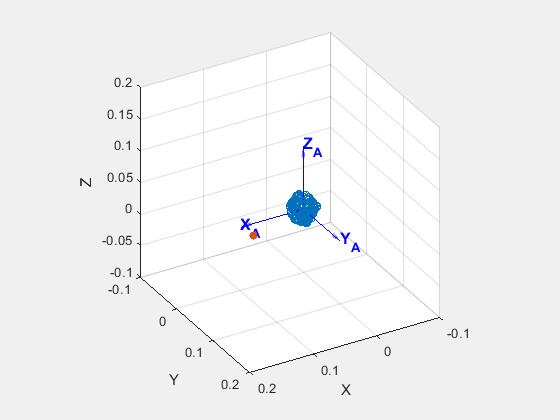

scatter3(x,y,z,'filled')



axis([-.1 0.2 -0.1 0.2 -0.1 0.2])

*First approach:**  Asume that the ZX plane of the Robot is aligned with the plane of symmetry of the human body.*

5.- Display all necessary Reference Frames

*Add your comemnts here.....be concise*

%% put your code Here

6.- Place the 6R Robot manipulator nearby the operating table to warranty that the head is in the reachable work space. Use a Puma 560.

*Add your comemnts here.....be concise*

%% put your code Here

7.- Get the transformation that maps tumor points in Robot Frame.

*Add your comemnts here.....be concise*

%% put your code Here

8.- Print the tumor points in Robot Frame.

*Add your comemnts here.....be concise*

%% put your code Here

9.- Prepare a script that perform a biopsy. Zoom in the scene

*Add your comemnts her**e.....be concise*

%% put your code Here

10.- Prepare a script that perform trepanation.

*Add your comemnts her**e.....be concise*

%% put your code Here

11.- Prepare a script that perform tumor burning with the laser.

*Add your comemnts her**e.....be concise*

%% put your code Here

*Second approach:**  Assume that the ZX plane of the Robot is not aligned with plane of symetry of the human body and it is needed a orientation calibration.*

12.-Get the transformation that maps tumor points in Robot Frame. See teacher help: Triangle.mlx

*Add your comemnts her**e.....be concise*

%% put your code Here

13.- Print the tumor points in Robot Frame.

*Add your comemnts her**e.....be concise*

%% put your code Here

14.-Use the script that perform a biopsy. Zoom in the scene

*Add your comemnts her**e.....be concise*

%% put your code Here

15.- Use the  script that perform trepanation.

*Add your comemnts her**e.....be concise*

%% put your code Here

16.- Use the script that perform tumor burning with the laser.

*Add your comemnts her**e.....be concise*

%% put your code Here